# Sample 8-1

## 離散コサイン変換

画像変換の効果

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete cosine transform

Effect of image transforms

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### %% 原画像の読込

pictureRgb = imread('data/barbaraFaceRgb.tif');
pictureGray = rgb2gray(pictureRgb);

### %% 原画像の表示

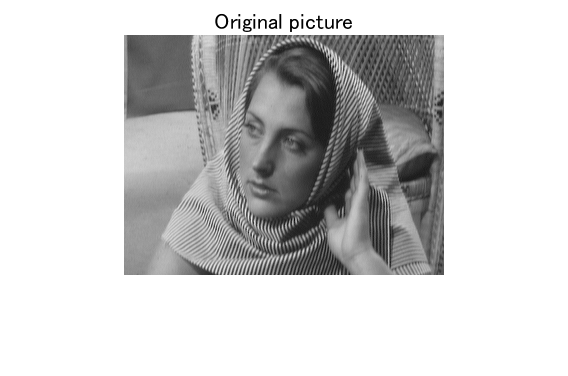

figure(1)
imshow(pictureGray)
title('Original picture')

### %% 二次元ベクトル集合の抽出

nPixels = numel(pictureGray);
setOfX = reshape(pictureGray.', 2, nPixels/2);

### %% 変換前の散布図

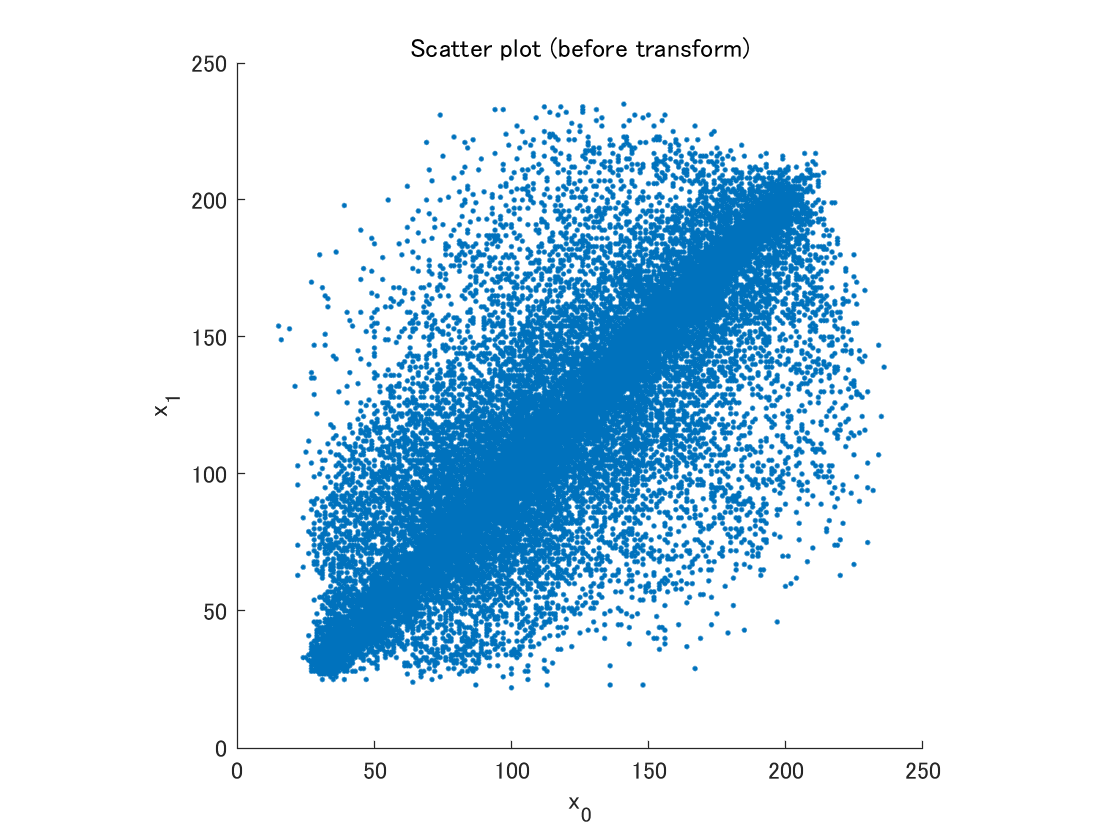

figure(2)
scatter(setOfX(1,:),setOfX(2,:),'.')
axis square
xlabel('x_0')
ylabel('x_1')
title('Scatter plot (before transform)')

### %% 信号変換

setOfY = 1 / sqrt(2) * [ 1 1 ; -1 1 ] * double(setOfX);

### %% 変換後の散布図

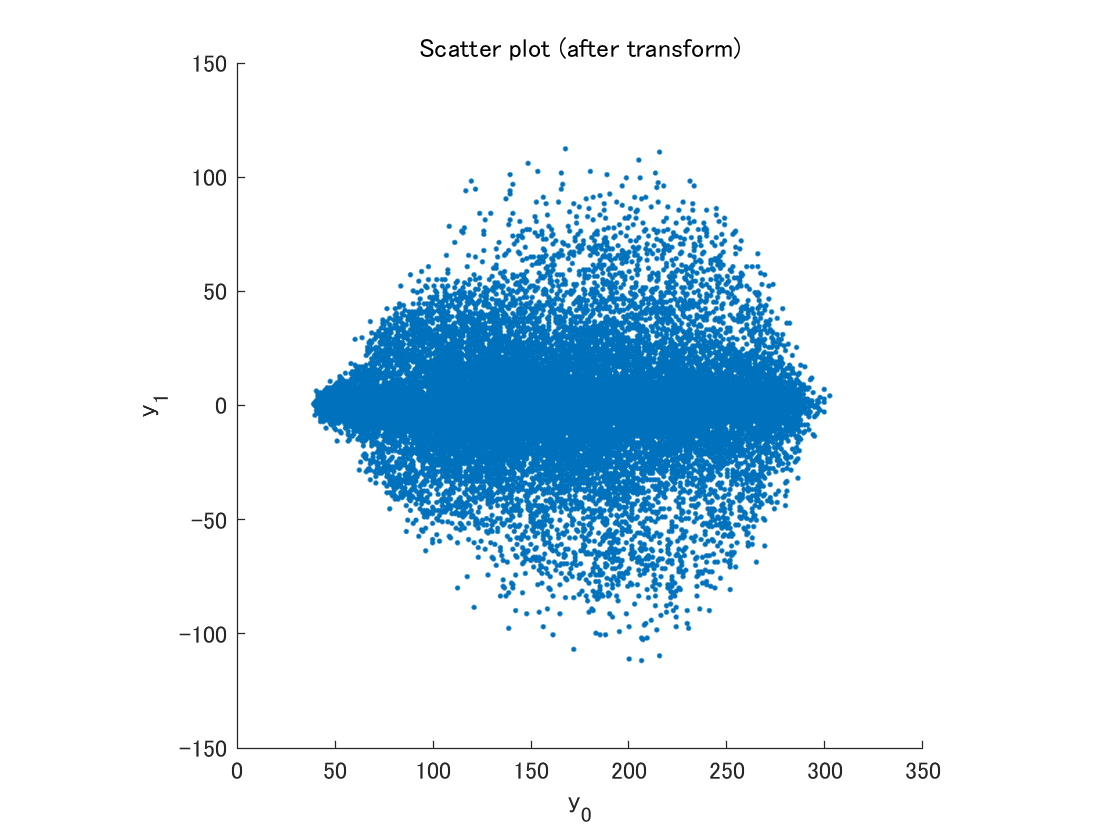

figure(3)
scatter(setOfY(1,:),setOfY(2,:),'.')
axis square
xlabel('y_0')
ylabel('y_1')
title('Scatter plot (after transform)')

© Copyright, Shogo MURAMATSU, All rights reserved.